# Homework 2

The influence of backlash in a control system will be discussed in this homework. Consider the drive line in a crane, where torque is generated by an electric motor, transformed through a gearbox, and finally used to lift a load. A block diagram describing the control of the angular position (aka, angular displacement) of the lifting axis $\theta_{out}$ is shown below. Here the first block represents the P-controller ($G_{e \rightarrow V} = K >0$), the second the dynamics in the motor ($G_{V \rightarrow \omega_{in}} = \frac{1}{T s + 1}$, with $T>0$), and the third the back-lash between the gear teeth in the gearbox (there is a dynamic relation between the angular velocity of the driving gear and the angular displacement of the driven gear).

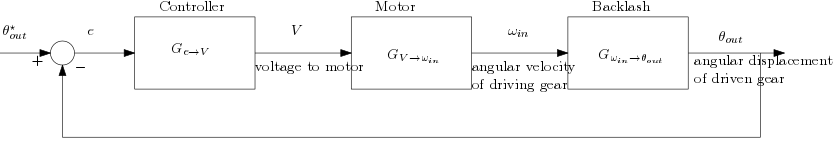

The backlash model gives a dynamic relation between the angular displacement of the driving gear (aka$\theta_{in}$) and the angular displacement of the driven gear (aka$\theta_{out}$). Another possibility is to model the backlash as the relation between the corresponding angular velocities $\omega_{in}$ and $\omega_{out}$. In this modeling approach,


$$\dot{\theta}_{out} 
= 
\omega_{out}(\theta_{out},\theta_{in},\omega_{in}) 
=
\begin{cases}
\omega_{in}
&
\text{if contact}(\theta_{out},\theta_{in},\omega_{in})
\\
0 & \text{otherwise} 
\end{cases} $$


where 


$$\text{contact}(\theta_{out},\theta_{in},\omega_{in}) 
= \text{True} 
\text{ if } 
| \theta_{in} - \theta_{out}| \ge \Delta
\wedge 
\omega_{in}(\theta_{in} - \theta_{out}) > 0,
\\
\text{contact}(\theta_{out},\theta_{in},\omega_{in}) 
= \text{False} 
\text{ otherwise}.$$


## 1 [1p]

Consider the back-lash model described as a block

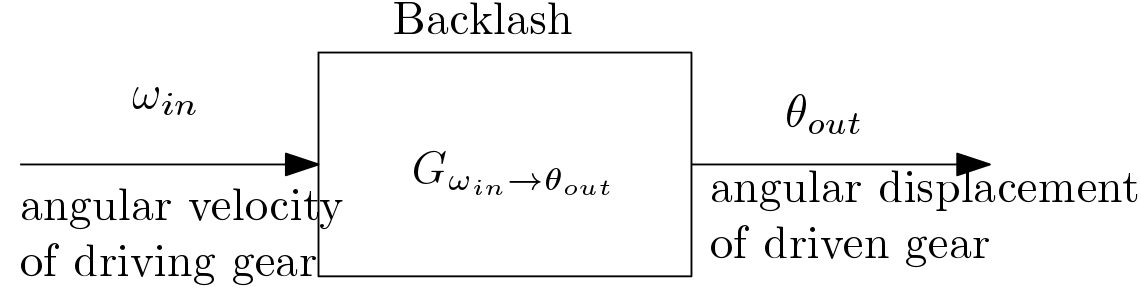

Take 


$$\omega_{in}:
R_{\ge 0} \ni t 
\mapsto 
\omega_{in}(t) = \begin{cases}
\,\,\, 1  & t \in [0,1)
\\
-1 & t \in [1,2)
\\
0 & t \in [2,\infty)
\end{cases}$$


as the input to the BL model (in open-loop). Sketch $\theta_{in}$, $\theta_{out}$, $\omega_{in}$, and $\omega_{out}$ for $(\theta_{in}(0),\theta_{out}) = (0,-\Delta)$ in a diagram. You may take $\Delta = 1$ degree, which means the driving gear can move 1 degree, while the drived gear stays at rest (experiment with other values for $\Delta$ if necessary).

## 2.1[1p]

Show that the gain of the BL system is equal to $\gamma(G_{\omega_{in} \rightarrow \theta_{out}})=1$. Show that the BL system is passive. Motivate why the BL system is bounded by a sector $[k_1,k_2] = [0,1]$.

## 3.1[1p] 

Consider the backlash model BL in a feedback loop,

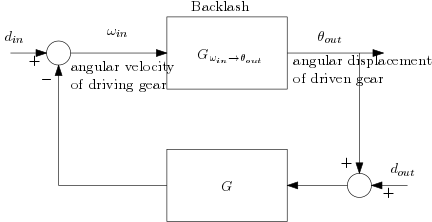

Here $d_{in}$ and $d_{out}$ represent disturbances. Assume that $G(s)$ is an arbitrary transfer function.

## 3.1a [1/3p] 

Given $\gamma(G_{\omega_{in} \rightarrow \theta_{out}})$ derived in Exercise $2$, which constraints are imposed on $G(s)$ by the Small Gain Theorem in order to have a BIBO stable closed-loop system (from ($d_{in}$, $d_{out}$) to $(\dot{\theta}_{in},\dot{\theta}_{out}) = (\omega_{in},\omega_{out})$)?

## 3.1b [1/3p] 

Which constraints are imposed on $G(s)$ by the Passivity Theorem in order to have a BIBO stable closed-loop system?

## 3.1c [1/3p] 

Which constraints are imposed on $G(s)$ by the Circle Criterion in order to have a BIBO stable closed-loop system?

## 4 [1p]

For the crane control system, the transfer function in Exercise 3 is equal to ($G_{V \rightarrow \omega_{in}}(s) = \frac{K}{1 + s T}$). For the  driving gear angular displacement, the transfer function is


$$G_{V \rightarrow \theta_{in}}(s) = \frac{K}{s(1 + s T)}$$


Motivate why BIBO stability (of $G_{V \rightarrow \theta_{in}}(s)$) cannot be concluded from the Small Gain Theorem or the Passivity Theorem. Let $T = 1$ and determine for which $K>0$ the Circle Criterion leads to BIBO stability.

## 5 [1p]

Along with the .mlx file you find a .mdl and a .m file (a simulink file and a script file, respectively). You may open the Simulink model by running 

hw2

After inspection of the block diagram in hw2.mdl, compare that with the block diagram in this homework. What disturbance is added in hw2? What $\Delta$ is chosen? Simulate the system with the controller $K = 0.25$ by running

K=0.25; 
macro

Does it seem like the closed-loop system is BIBO stable from $d_{in}$ to $(\dot{\theta}_{in},\dot{\theta}_{out})$? Why cannot the closed-loop system be BIBO stable from $d_{in}$ to $(\theta_{in},\theta_{out})$? Try other controller gains (for instance, $K=0.5$ and $K=4$). Compare with your conclusions in Exercise 4. Compare your results to the case when the backlash is neglected.